# Determinsitic Parameterization

This live script corresponds to section 2 of the paper *Parameterizing the impact of unresolved temperature variability on the large scale density field Part I: Theory* where we develop a deterministic parameterization of the effect of subgrid scale temperature and salinity fluctuations on the calculation of the large scale density. For the paper we compute all statistics for 73 snapshots, which corresponds to 1 model year. We have uploaded relevant fields at nominal 1 degree resolution. In this live script we demonstrate important calculations for one snapshot. Note that the R^2 and other statistical values in the paper are the average over 73 snapshots, so they do not exactly match the values in this script. All the code we used is included in the repoistory. The full data set is available upon request. 

## One snapshot: January 5th, 1989

load('0013_01_05_1degree_a.mat')
load('0013_01_05_1degree_c.mat')

## Model for error in density

Our first model for the error in density is


$$    \bar{\rho}(\mathbf{x}_0)- \rho_m(\mathbf{x}_0) \approx 
    \frac{\partial_T^2 \widehat{\rho}(\bar{T}, \bar{S})}{2} \overline{\Delta T^2}
       + 
      \partial_T\partial_S \widehat{\rho}(\bar{T}, \bar{S})\overline{\Delta T \Delta S}
      + \frac{\partial_S^2\widehat{\rho}(\bar{T}, \bar{S})}{2} \overline{\Delta S^2}.$$


This model is very good with R^2 = 0.999.

% diagnosed error in density
rho_mdl = dens_wright_eos(tbar, sbar, pbar) ; % density, as calculated by a FV ocean model
delta_rho = rho_bar - rho_mdl ; % difference between large scale density and density calculated by FV model

% model for error in density

[rho_tt, rho_ts, rho_ss] = dens_wright_sot(tbar, sbar, pbar) ; % second derivatives of the equation of state
term_tt = 0.5 .* sgs_t_var .* rho_tt ; % second order temperature term
term_ts = sgs_ts_covar .* rho_ts ; % second order temperature/salinity cross term
term_ss = 0.5 .* sgs_s_var .* rho_ss ; % second order salinity term
three_term_taylor = term_tt + term_ts + term_ss ; % all three second order terms

% R^2 value
r2 = r_squared(three_term_taylor, delta_rho);
fprintf('The R^2 value associated with the model shown above is %g.\n', r2)

The R^2 value associated with the model shown above is 0.999676.


We see that the temperature term is an order of magnitude larger than either of the other terms, and thus the simplified model, 


$$    \bar{\rho}(\mathbf{x}_0)- \rho_m(\mathbf{x}_0) \approx 
    \frac{\partial_T^2 \widehat{\rho}(\bar{T}, \bar{S})}{2} \overline{\Delta T^2}$$


is still a good model for the error in density, with R^2 = 0.994 (average over one year).

fprintf('The average magnitude of the temperature term is %.2e\n', nanmean(abs(term_tt(:))) )

The average magnitude of the temperature term is 5.14e-04


fprintf('The average magnitude of the cross term is %.2e\n', nanmean(abs(term_ts(:))) )

The average magnitude of the cross term is 2.83e-05


fprintf('The average magnitude of the salinity term is %.2e', nanmean(abs(term_ss(:))) )

The average magnitude of the salinity term is 4.52e-07

r2_tt = r_squared(term_tt, delta_rho);
fprintf('The R^2 value associated with the model using only the temperature term is %g.\n', r2_tt)

The R^2 value associated with the model using only the temperature term is 0.995637.


## Parameterization of subgrid scale temperature variance

We propose the following simple model for the subgrid scale temperature variance

$
 \overline{\Delta T^2} \approx c\cdot |\delta \mathbf{x} \circ \nabla \bar{T}|^2$.

sgs_t_var_mdl = len_grad(tbar) ;

We need to estimate the coefficient c. We minimize Huber's loss because it is more robust to outliers than the standard squared loss minimized in ordinary least squares regression.

nonan = ~isnan(sgs_t_var(:)+sgs_t_var_mdl(:)) ;
x = sgs_t_var_mdl(nonan) ;
y = sgs_t_var(nonan) ;

% OLS: forcing intercept to be zero
b = (x'* x)\ (x'*y) ;
err = abs( y - ( b.* x ) ) ;
fprintf('The OLS estimator for c is %g.\n', b)

The OLS estimator for c is 0.242617.


% set threshold between quadratic and linear loss to be
% 90th percentile of OLS errors
alpha_prctile = 0.9 ;
delta = prctile(err, 100*alpha_prctile) ;

% find minimizer of huber's loss
betas = 0:.001:0.3 ;
huber = zeros(size(betas)) ;
for i = 1:length(betas)
    huber(i) = huber_loss(x, y, betas(i), delta) ;
end
[C, Iall] = min(huber) ; 
fprintf('The line of best fit with intercept 0, estimated by minimizing Hubers loss, has slope %g.\n', betas(Iall))

The line of best fit with intercept 0, estimated by minimizing Hubers loss, has slope 0.192.


Using this parameterization of subgrid scale temperature variance, we find a reasonable model of the error in density with R^2 = 0.546

c = 0.20;
r2_sgs = r_squared(c.*sgs_t_var_mdl, sgs_t_var);
fprintf('The R^2 value for the model of subgrid scale temperature variance is %.2g.\n', r2_sgs)

The R^2 value for the model of subgrid scale temperature variance is 0.6.


fprintf('The L2 pattern correaltion for the subgrid scale temperature variance is %.2g.\n',...
    sum(x.*y)/(sqrt(sum(x.*x))*sqrt(sum(y.*y)))

The L2 pattern correaltion for the subgrid scale temperature variance is 0.8.



delta_rho_mdl = 0.5 .* c.* sgs_t_var_mdl .* rho_tt ;

Undefined function or variable 'rho_tt'.

r2_mdl = r_squared(delta_rho_mdl, delta_rho);
fprintf('The R^2 value for the model of the error in density is %.2g.\n', r2_mdl)

nonan2 = ~isnan(delta_rho_mdl(:)+delta_rho(:)) ;
x2 = delta_rho_mdl(nonan) ;
y2 = delta_rho(nonan) ;

fprintf('The L2 pattern correaltion for the error in density is %.2g.\n',...
    sum(((x2-mean(x2)).*(y2-mean(y2))))/(sqrt(sum((x2-mean(x2)).*(x2-mean(x2))))*sqrt(sum((y2-mean(y2)).*(y2-mean(y2))))))

## Diagnosed vs Modeled Error in Density

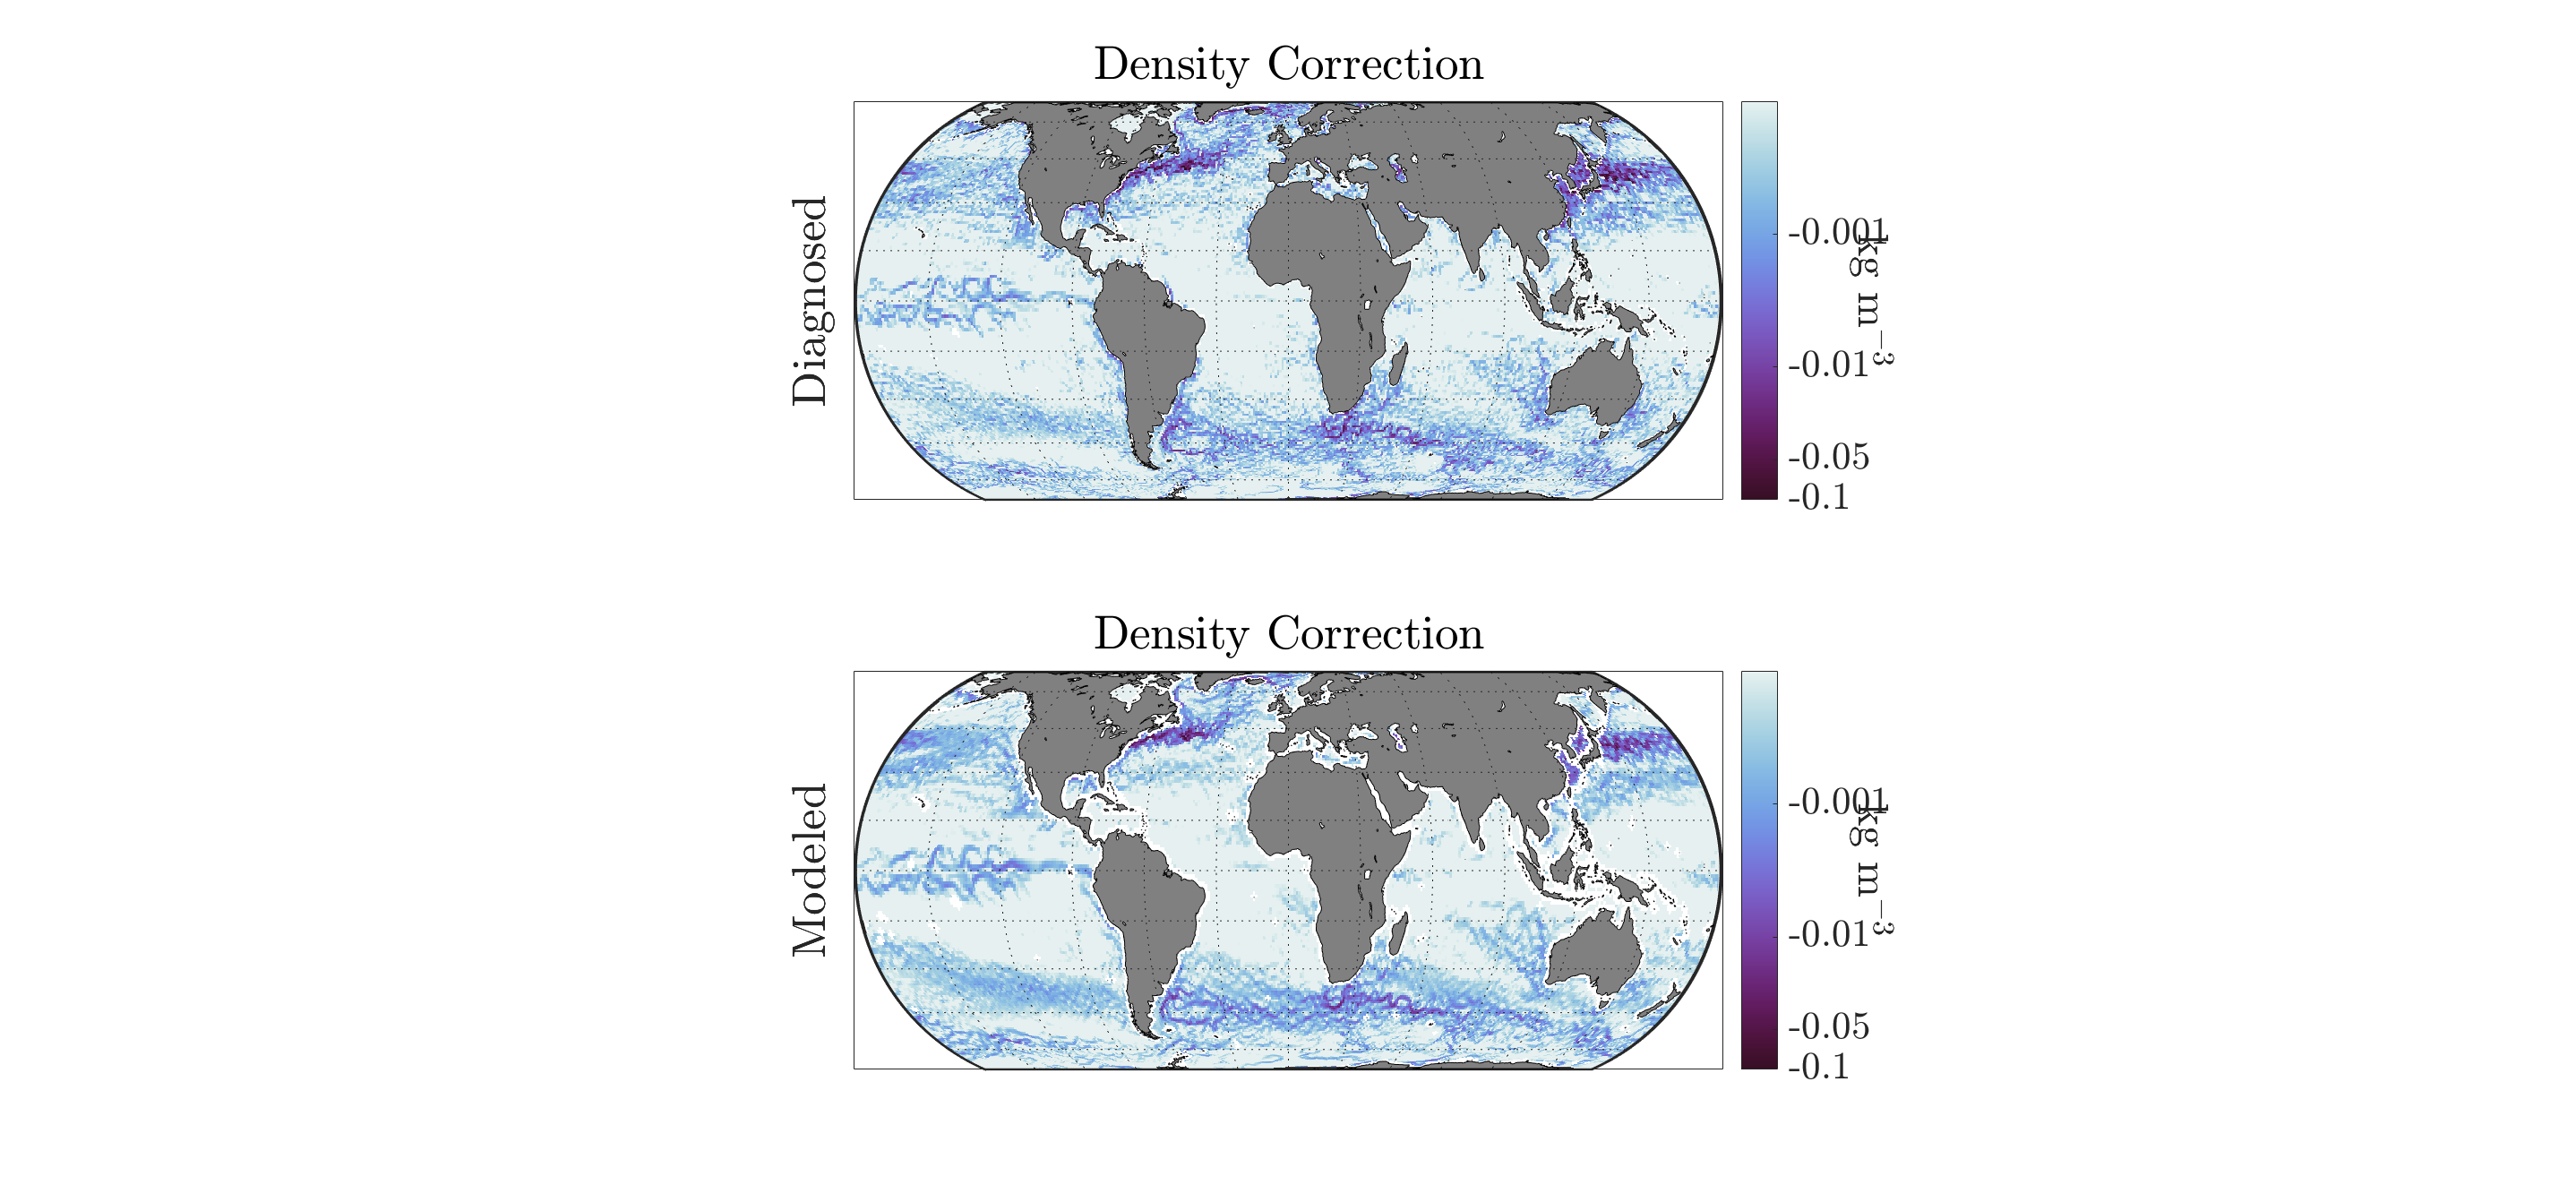

%%
% plot diagnosed error in density
%%
figure
subplot(2,1,1)
axesm('eckert4', 'MapLatLim', [-70, 70]); 
t=geoshow(circshift(ulat, [0,70]), circshift(ulon, [0, 70]), circshift(-log10(abs(delta_rho(:,:,1))), [0, 70]),... 
    'DisplayType', 'texturemap');
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5] );
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(~isnan(delta_rho(:,:,1)), [0,70])))

% colorbar
cmocean('-dense');
set(gca, 'clim', [1 4])
cvals = [-0.1, -0.05, -0.01, -0.001] ;
cbar=colorbar('Ticks', -log10(-cvals), 'TickLabels', cvals);
cbar.Label.String = 'kg m$^{-3}$'; cbar.Label.Interpreter = 'latex';
cbar.Label.Rotation = -90;
cbar.Label.Margin = 8; cbar.TickLabelInterpreter = 'latex';

% title and labels
title('Density Correction', 'Interpreter','latex')
ylabel('Diagnosed', 'Interpreter', 'latex')
set(gca, 'FontSize', 48)
cbar.FontSize = 36;
set(gcf, 'Position',[100 100 1500 700])
pbaspect([2.5 1 1])
framem; gridm; tightmap

%%
% plot modeled error in density
%%
subplot(2,1,2)
axesm('eckert4', 'MapLatLim', [-70, 70]); 
t=geoshow(circshift(ulat, [0,70]), circshift(ulon, [0, 70]), circshift(-log10(abs(delta_rho_mdl(:,:,1))), [0, 70]),... 
    'DisplayType', 'texturemap');
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5] );
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(~isnan(delta_rho_mdl(:,:,1)), [0,70])))

% colorbar
cmocean('-dense');
set(gca, 'clim', [1 4])
cvals = [-0.1, -0.05, -0.01, -0.001] ;
cbar = colorbar('Ticks', -log10(-cvals), 'TickLabels', cvals);
cbar.Label.String = 'kg m$^{-3}$'; cbar.Label.Interpreter = 'latex';
cbar.Label.Rotation = -90;
cbar.Label.Margin = 8; cbar.TickLabelInterpreter = 'latex';

% title and labels
title('Density Correction', 'Interpreter','latex')
ylabel('Modeled', 'Interpreter', 'latex')
set(gca, 'FontSize', 48)
cbar.FontSize = 36;
set(gcf, 'Position',[100 100 1500 700])
pbaspect([2.5 1 1])
framem; gridm; tightmap

%%
%% plot difference in diagnosed vs modeled subgrid scale temperature variance
%% 
axesm('eckert4', 'MapLatLim', [-70, 70]); 
framem; gridm; tightmap;
t = geoshow(circshift(ulat, [0,70]), circshift(ulon, [0,70]), circshift(delta_rho(:,:,1)- delta_rho_mdl(:,:,1), [0,70]),...
    'DisplayType', 'texturemap');
set(gca, 'clim', [-0.02, 0.02], 'FontSize', 14)
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5]);
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(~isnan(delta_rho(:,:,1)- delta_rho_mdl(:,:,1)), [0,70])));

% colorbar
%colormap pink
cmocean('balance');
cbar = colorbar;
set(gca, 'clim', [-0.02, 0.02])
cbar.Label.String = 'kg m$^{-3}$'; cbar.Label.Interpreter = 'latex';
cbar.Label.Rotation = -90;
cbar.Label.Margin = 8; cbar.TickLabelInterpreter = 'latex';

% title and labels
title('Density Correction', 'Interpreter','latex')
ylabel('Difference', 'Interpreter', 'latex')
set(gca, 'FontSize', 48)
cbar.FontSize = 36; 
set(gcf, 'Position',[100 100 1500 700])
pbaspect([2.5 1 1])
framem; gridm; tightmap

## Diagnosed vs Modeled Subgrid Scale Temperature Variance

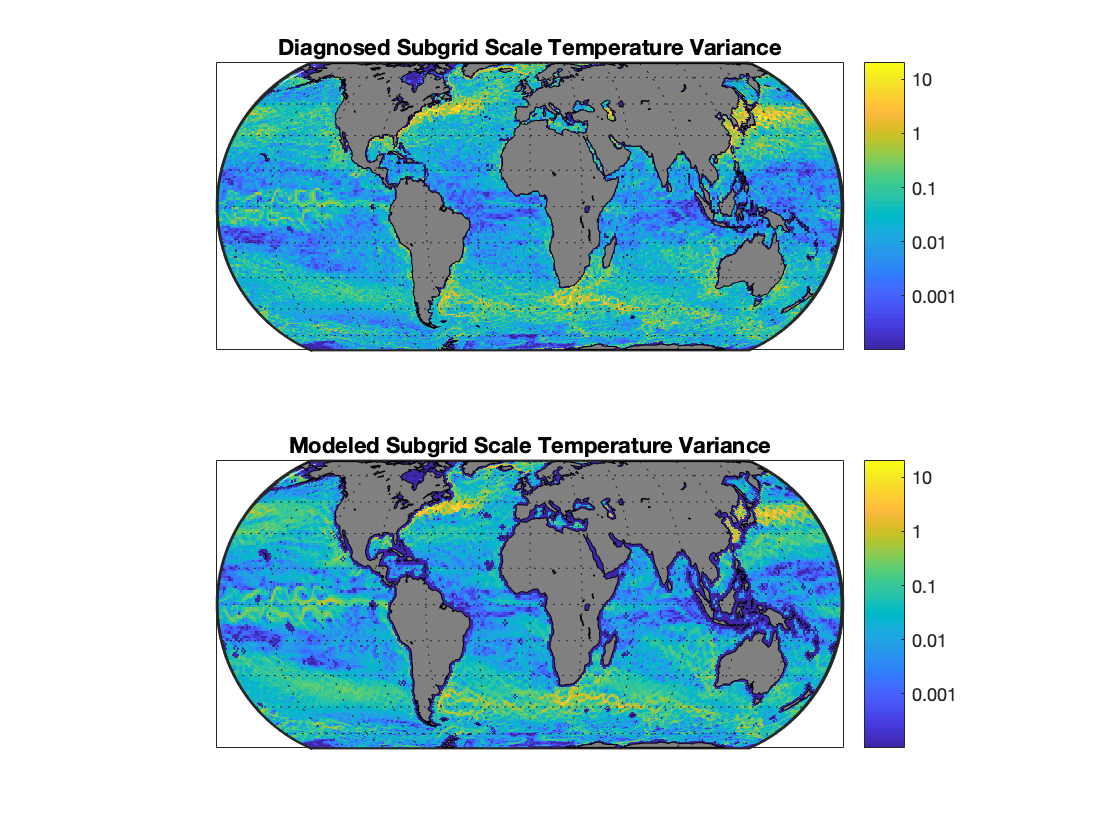

%%
% plot diagnosed subgrid scale temperature variance
%%
figure
subplot(2,1,1)
axesm('eckert4', 'MapLatLim', [-70, 70]); 
framem; gridm; tightmap;
t = geoshow(circshift(ulat, [0,70]), circshift(ulon, [0,70]), circshift(log10(sgs_t_var(:,:,1)), [0,70]),...
    'DisplayType', 'texturemap');
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5]);
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(~isnan(sgs_t_var(:,:,1)), [0,70])))

% colorbar
cmocean('matter')
set(gca, 'clim', [-4, log10(20)])
cvals = [0.001, 0.01, 0.1, 1, 10] ;
cbar = colorbar('Ticks', log10(cvals), 'TickLabels', cvals);
cbar.Label.String = '$(^\circ \textrm{C})^2$'; cbar.Label.Interpreter = 'latex';
cbar.Label.Rotation = -90;
cbar.Label.Margin = 8; cbar.TickLabelInterpreter = 'latex';

% title and labels
title('Subgrid Scale Temperature Variance', 'Interpreter','latex')
ylabel('Diagnosed', 'Interpreter', 'latex')
set(gca, 'FontSize', 48)
cbar.FontSize = 36; 
set(gcf, 'Position',[100 100 1500 700])
pbaspect([2.5 1 1])
framem; gridm; tightmap

%%
% plot modeled subgrid scale temperature variance
%%
subplot(2,1,2)
axesm('eckert4', 'MapLatLim', [-70, 70]); 
framem; gridm; tightmap;
t=geoshow(circshift(ulat, [0,70]), circshift(ulon, [0,70]), circshift(log10(c.*sgs_t_var_mdl(:,:,1)), [0,70]),... 
    'DisplayType', 'texturemap');
geoshow('landareas.shp', 'FaceColor', [0.5 0.5 0.5]);
t.AlphaDataMapping = 'none'; % interpet alpha values as transparency values
t.FaceAlpha = 'texturemap'; % Indicate that the transparency can be different each pixel
alpha(t,double(circshift(~isnan(sgs_t_var_mdl(:,:,1)), [0,70])))

% colorbar
cmocean('matter')
set(gca, 'clim', [-4, log10(20)])
cvals = [0.001, 0.01, 0.1, 1, 10] ;
cbar = colorbar('Ticks', log10(cvals), 'TickLabels', cvals);
cbar.Label.String = '$(^\circ \textrm{C})^2$'; cbar.Label.Interpreter = 'latex';
cbar.Label.Rotation = -90;
cbar.Label.Margin = 8; cbar.TickLabelInterpreter = 'latex';

% title and labels
title('Subgrid Scale Temperature Variance', 'Interpreter','latex')
ylabel('Modeled', 'Interpreter', 'latex')
set(gca, 'FontSize', 48)
cbar.FontSize = 36; 
set(gcf, 'Position',[100 100 1500 700])
pbaspect([2.5 1 1])
framem; gridm; tightmap

## Coefficient of Proportionality at Different Resolutions

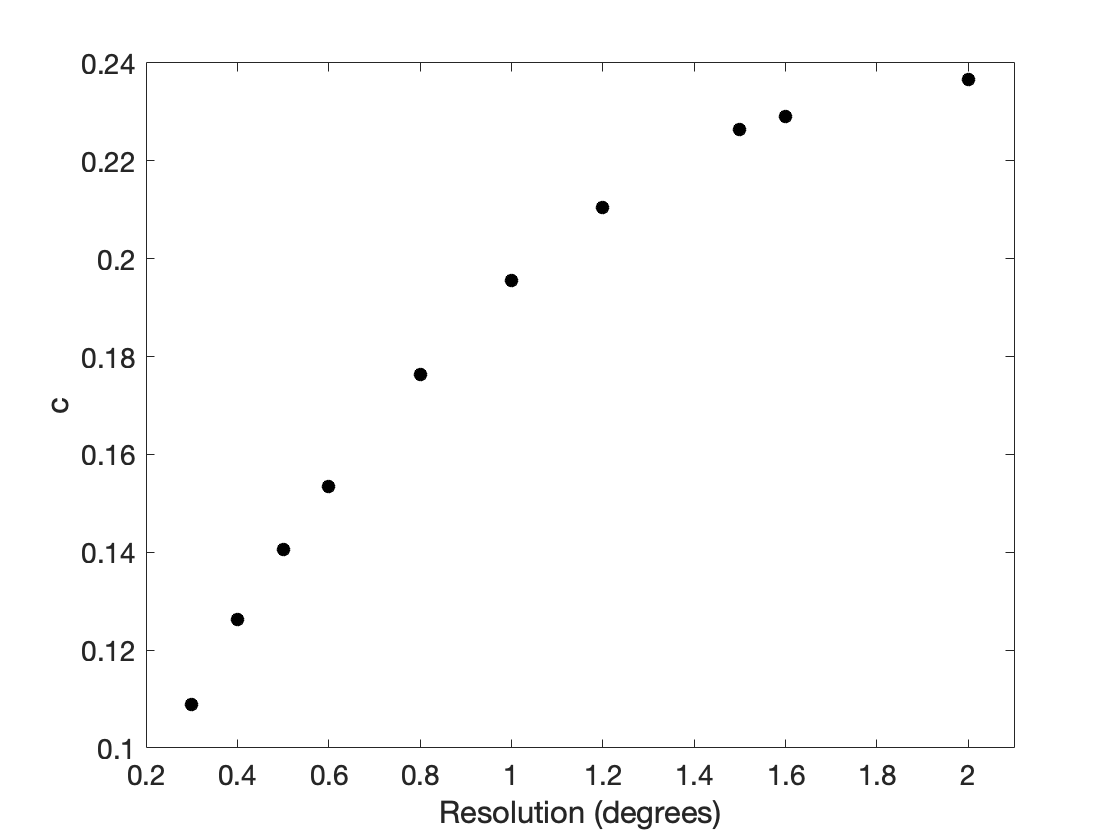

% plot coefficient of proportionality vs resolution
plot((1:20)./10, coef, 'o', 'Color', 'k', 'MarkerFaceColor', 'k');
xlabel('Resolution (degrees)');
ylabel('c');
xlim([0.2, 2.1]);
xticks(0.2:0.2:2.0)
set(gca,'fontsize', 14)

## Option 2 for a third panel in figure 1: 

histogram2(log10(sgs_t_var_mdl), log10(sgs_t_var), 'DisplayStyle','tile', 'HandleVisibility','off');
xlim([-11, 2])
ylim([-11, 2])
rline = refline(1, log10(c));
rline.Color = 'red';
rline.LineWidth = 2.5;
rline.LineStyle = '--';
xlim([-11, 2])
ylim([-11, 2])
yticks(-10:2:2)
xticks(-10:2:2)
hAxes = gca;
hAxes.TickLabelInterpreter = 'latex';

% title and labels
title('Subgrid Scale Temperature Variance', 'Interpreter','latex')
set(gca, 'FontSize', 36)
cmocean('matter')
cbar = colorbar;
cbar.TickLabelInterpreter = 'latex';
cbar.FontSize = 24; 
set(gcf, 'Position',[100 100 1400 700])
pbaspect([1 1 1])
daspect([1 1 1])
ylabel('\textrm{Diagnosed, }$\log_{10}(\sigma_T^2)$', 'Interpreter', 'latex')
xlabel('$\textrm{Modeled, }\log_{10}(|${\boldmath$\delta$}$\mathbf{x}\circ \nabla \bar{T}|^2)$', 'Interpreter','latex')
leg = legend('Deterministic Model', 'Location', 'southeast');
leg.Interpreter = 'latex';

leg =   Legend (Deterministic Model) with properties:

         String: {'Deterministic Model'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 32.4000
       Position: [0.3129 0.8423 0.2362 0.0613]
          Units: 'normalized'

  Show all properties


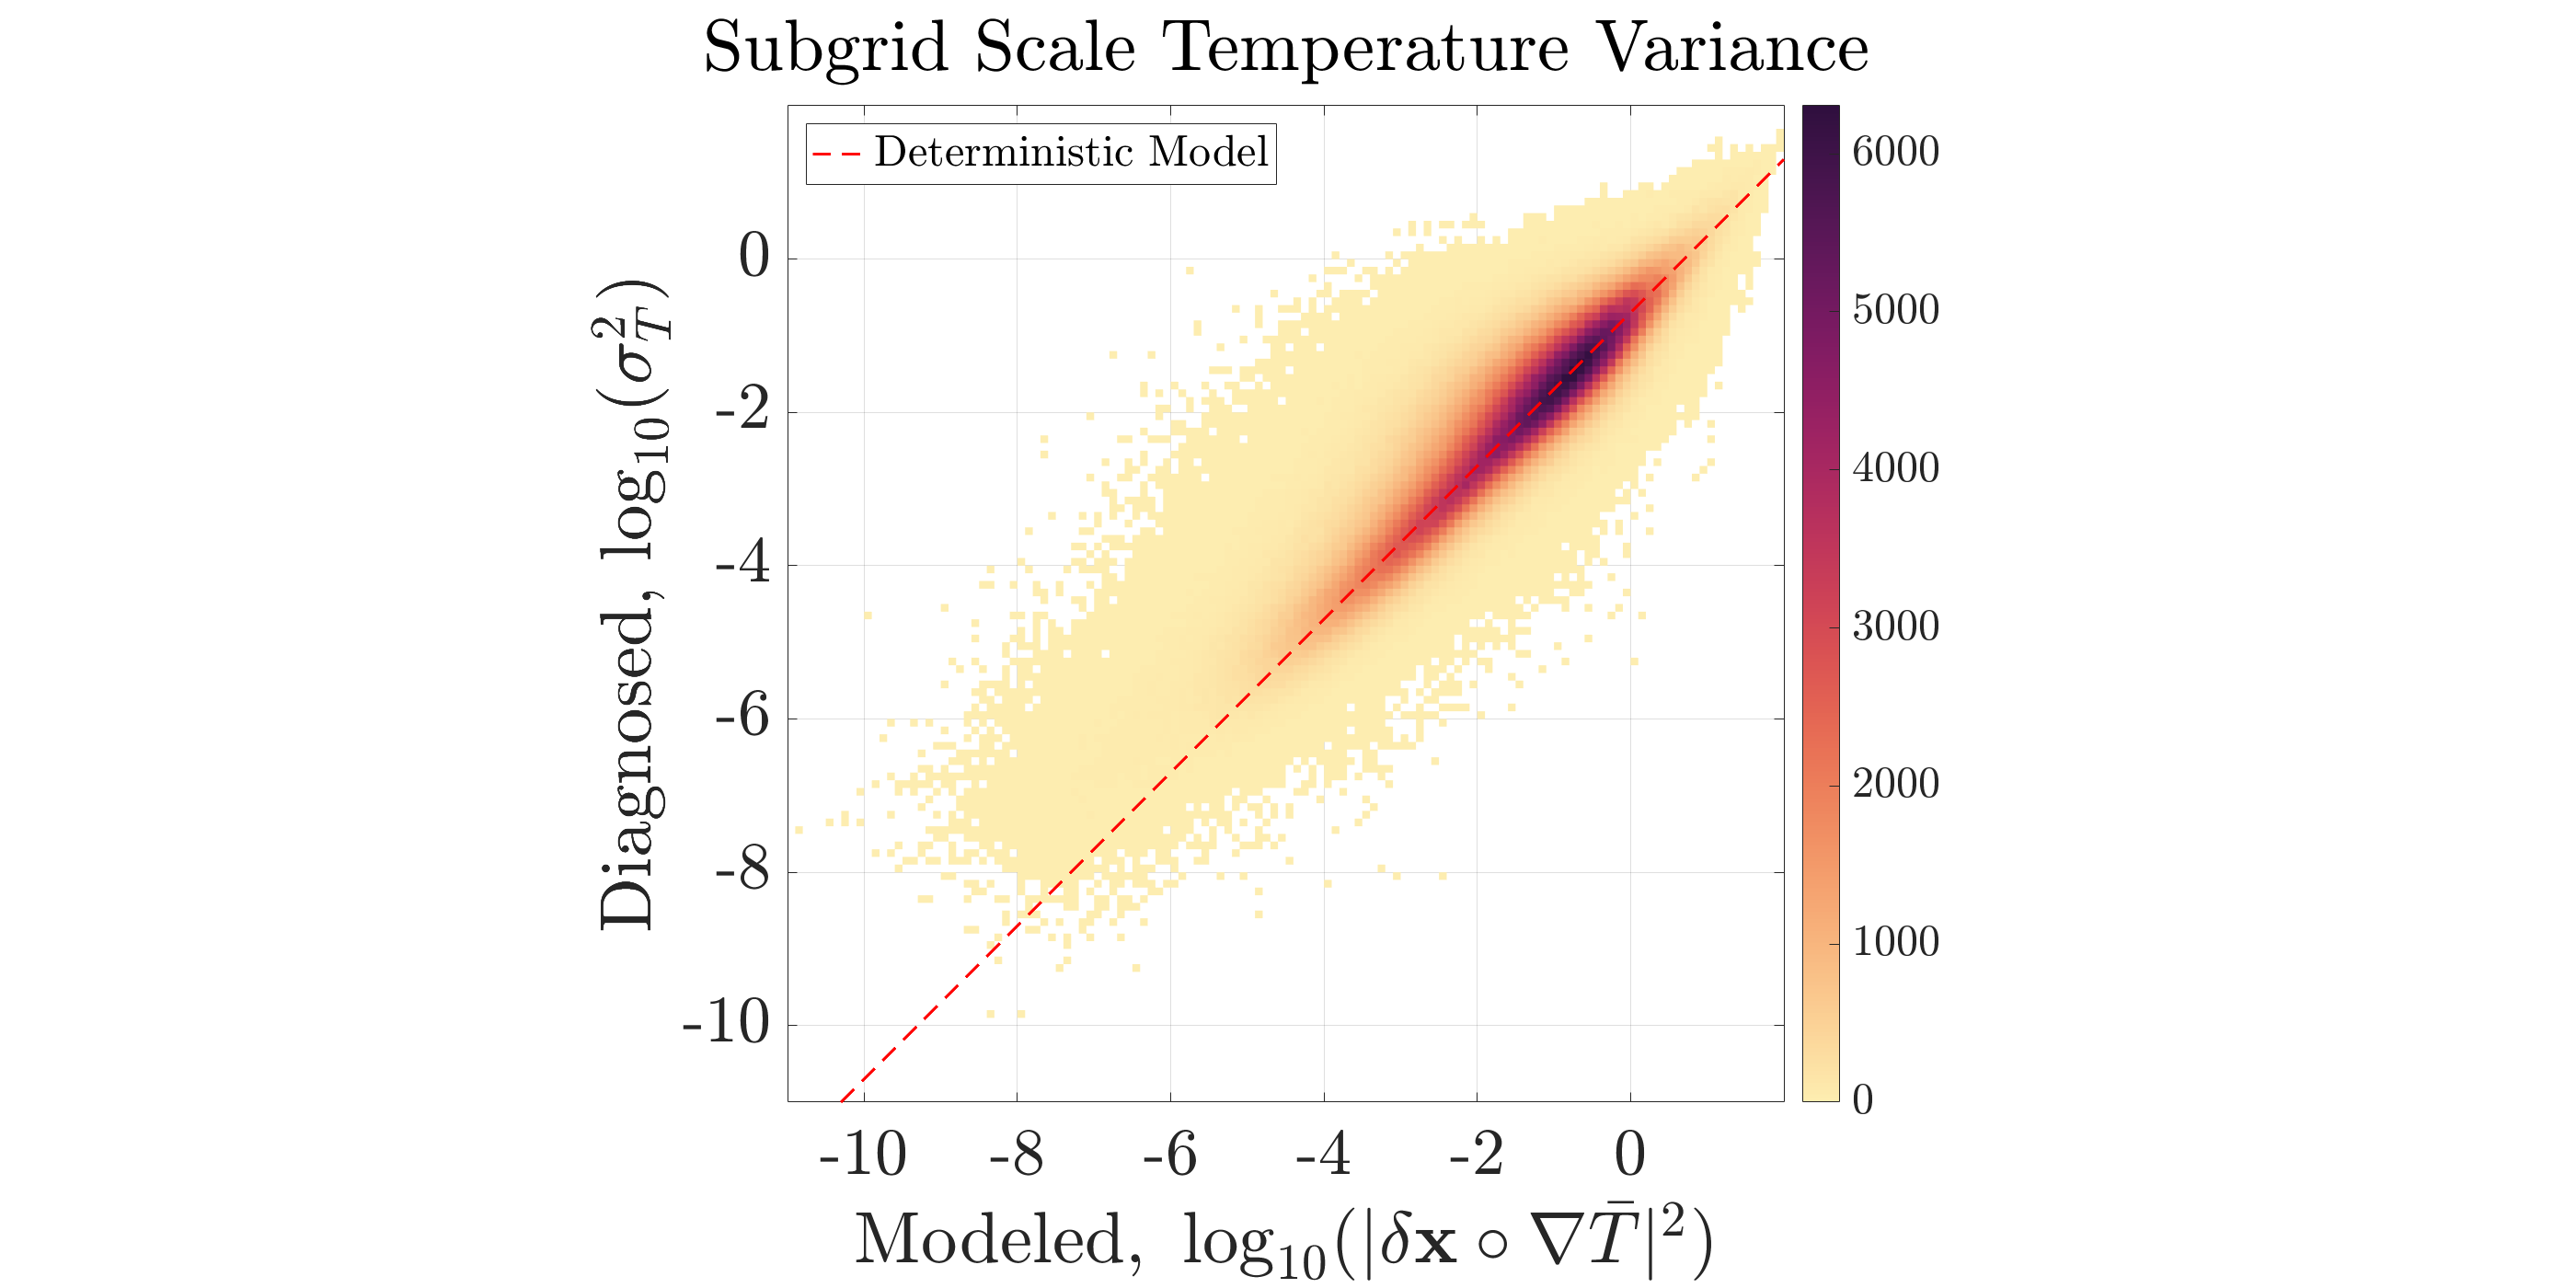

leg.FontSize = 24;